# Single Perceptron

In this exercise, we will take a list of 100 grocery runs where the quantities of 5 items purchased are known, along with the total price of each run. To learn the price of each individual item, we will train a single perceptron with stochastic gradient descent.

Helpful blog: https://towardsdatascience.com/power-of-a-single-neuron-perceptron-c418ba445095

## Set up the training data

The shopping lists are like our x-training data...the vectors from which our perceptron will make estimates. The total prices of the grocery runs are our y-training data...the values to which our perceptron's estimates will be compared to calculate cost.

training_data = csvread("grocery_training_data.csv",1);
shopping_lists = training_data(:,1:5);
total_prices = training_data(:,6);

## Set up variables to be stored during training

Note: when I say cost, I am not talking about the groceries. That is the function used to assess the error in the perceptron's estimates calculated as $C = \frac{1}{2}(y - \hat{y})^2$.

weights = zeros(5,size(shopping_lists,1)); % weights are equivalent to prices of each item in this example
cost = zeros(1,size(shopping_lists,1));
y_est = zeros(5,size(shopping_lists,1));

## Define hyperparameters and initialize random weights (item prices).

learning_rate = 0.001;
weights(:,1) = rand(5,1)*5; % We initialize assuming grocery items will cost $0-$5

## Let's train a perceptron!

We are going to calculate an estimate of total price ($\hat{y}$ ) using our randomly initialized item prices and compare it to the actual price of the grocery run ($y$) using the cost function. Then the gradients or partial derivatives of cost with respect to each weight $\frac{dC}{dw_i} = \frac{1}{2} * 2(y - \sum w_ix_i)(-x_i)$ can be used to update the weights. Iterating over this process, we should be able to hone in on the correct item prices. 

for shopping_run = 1:size(shopping_lists,1)
    y_est(shopping_run) = dot(shopping_lists(shopping_run,:), weights(:,shopping_run));
    cost(shopping_run) = 0.5*(total_prices(shopping_run,:)-y_est(shopping_run))^2;
    dc_dw = 2*0.5*-shopping_lists(shopping_run,:)*(total_prices(shopping_run,:)-y_est(shopping_run));
    weights(:, shopping_run +1) = weights(:, shopping_run) - learning_rate * transpose(dc_dw);
end

weights(:,end)

ans =     1.1264
    3.4108
    0.6308
    2.5440
    2.5698


## Let's see how our perceptron learned

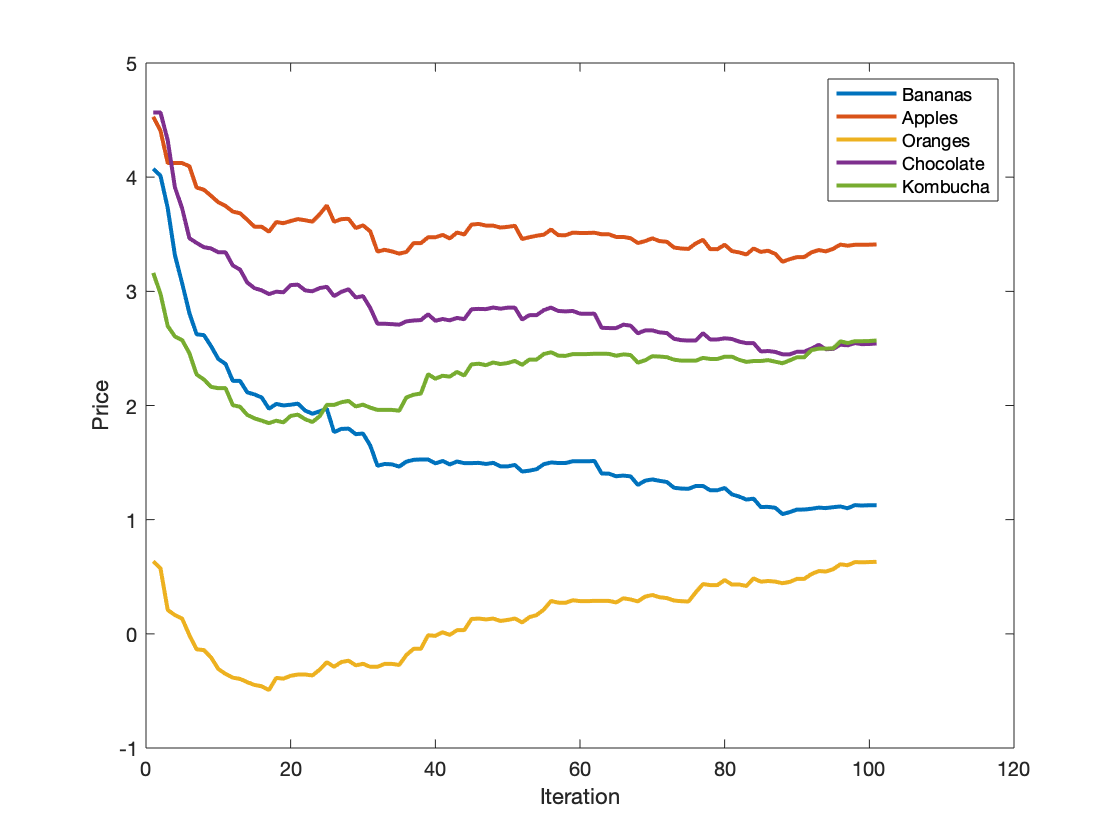

figure()
plot(weights(1,:),'LineWidth',2)
hold on
plot(weights(2,:),'LineWidth',2)
hold on
plot(weights(3,:),'LineWidth',2)
hold on
plot(weights(4,:),'LineWidth',2)
hold on
plot(weights(5,:),'LineWidth',2)
xlabel('Iteration')
ylabel('Price')
legend('Bananas','Apples','Oranges','Chocolate','Kombucha')

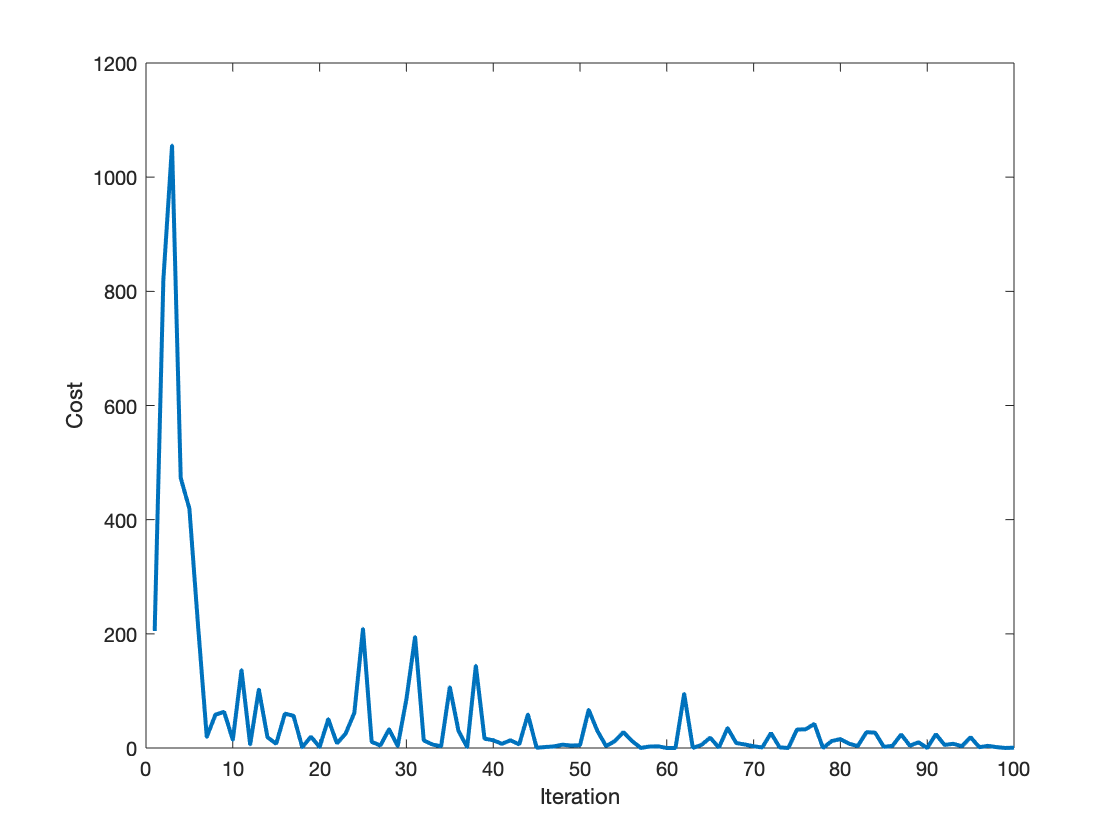

figure()
plot(cost,'LineWidth',2)
xlabel('Iteration')
ylabel('Cost')

% Hmmmm, it doesn't look like it settled very well on any prices, and our
% cost isn't settled at 0. We could try a couple
% things. Let's try introducing the concept of epochs to allow more
% training time. (We could also increase learning rate to see if that
% helps...maybe later

## Same perceptron, but with the ability to iterate over the training data for multiple epochs

n_epochs = 10;
cost_ep = zeros(1,size(shopping_lists,1)*n_epochs);
y_est_ep = zeros(1,size(shopping_lists,1)*n_epochs);
weights_ep = zeros(5,size(shopping_lists,1)*n_epochs + 1);
weights_ep(:,1) = rand(5,1)*5;
for epoch = 1:n_epochs
    for shopping_run = 1:size(shopping_lists,1)
        y_est_ep((epoch -1)*size(shopping_lists,1) + shopping_run) = dot(shopping_lists(shopping_run,:), weights_ep(:,(epoch -1)*size(shopping_lists,1) + shopping_run));
        cost_ep((epoch -1)*size(shopping_lists,1) + shopping_run) = 0.5*(total_prices(shopping_run,:)-y_est_ep((epoch -1)*size(shopping_lists,1) + shopping_run))^2;
        dc_dw = 2*0.5*-shopping_lists(shopping_run,:)*(total_prices(shopping_run,:)-y_est_ep((epoch -1)*size(shopping_lists,1) + shopping_run));
        weights_ep(:, (epoch -1)*size(shopping_lists,1) + shopping_run +1) = weights_ep(:, (epoch -1)*size(shopping_lists,1) + shopping_run) - learning_rate * transpose(dc_dw);
    end
end
weights_ep(:,end)

ans =     0.4957
    2.8521
    1.6320
    2.2520
    2.8887


## Let's see if that was any better

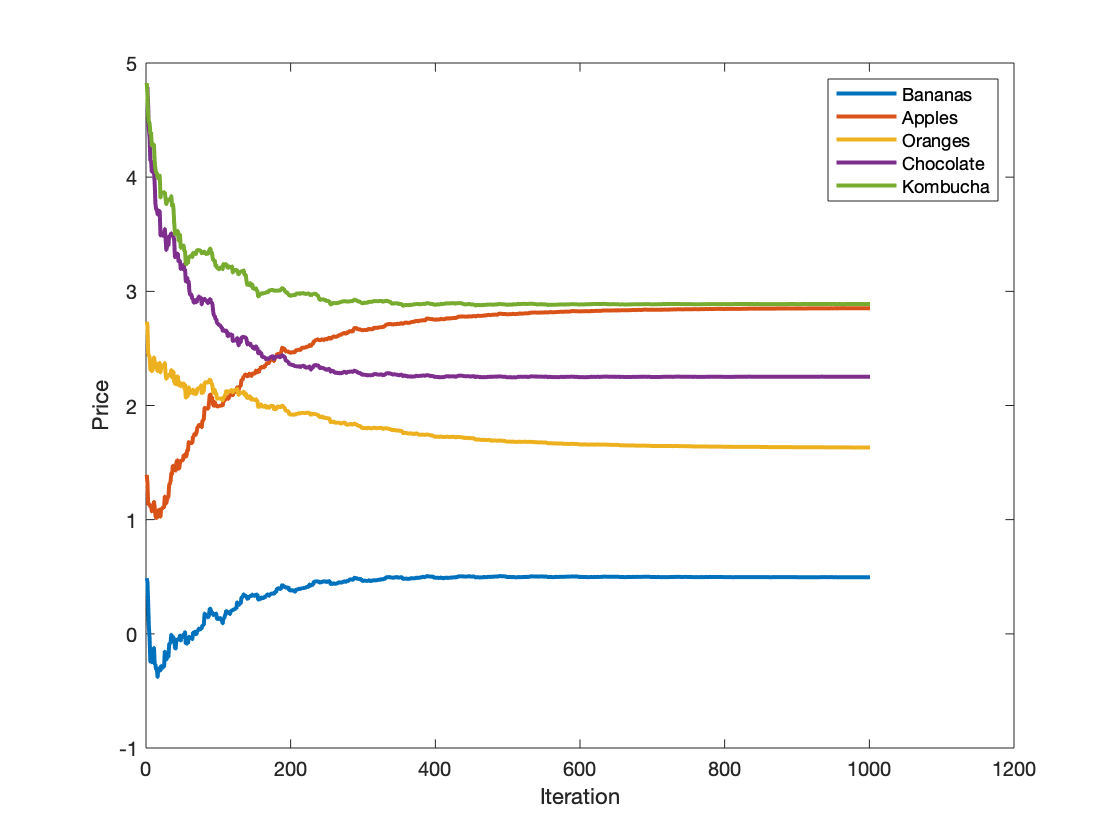

figure()
plot(weights_ep(1,:),'LineWidth',2)
hold on
plot(weights_ep(2,:),'LineWidth',2)
hold on
plot(weights_ep(3,:),'LineWidth',2)
hold on
plot(weights_ep(4,:),'LineWidth',2)
hold on
plot(weights_ep(5,:),'LineWidth',2)
xlabel('Iteration')
ylabel('Price')
legend('Bananas','Apples','Oranges','Chocolate','Kombucha')

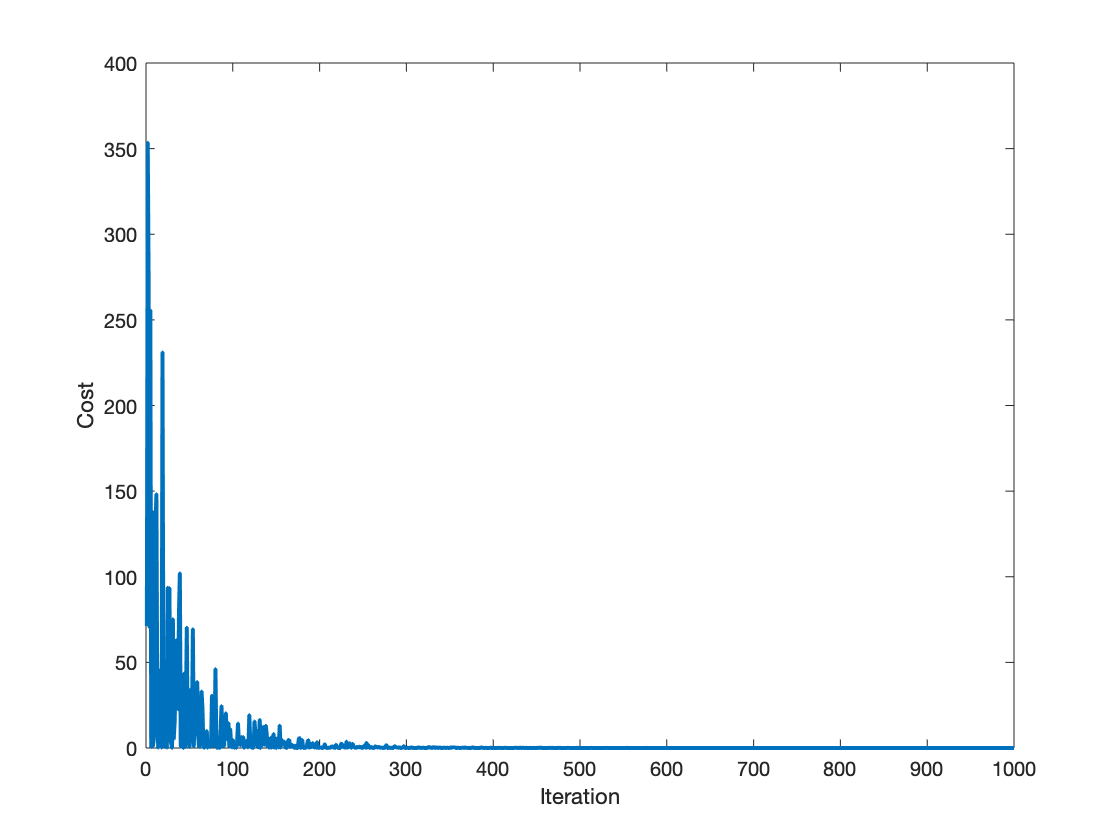


figure()
plot(cost_ep,'LineWidth',2)
xlabel('Iteration')
ylabel('Cost')

## What if I just gave it a single example and ran it a bunch of times....whould it get the right result?

n_iters = 1000;
cost_1ex = zeros(1,n_iters);
y_est_1ex = zeros(1,n_iters);
weights_1ex = zeros(5,n_iters + 1);
weights_1ex(:,1) = rand(5,1)*5;
for i = 1:n_iters
    y_est_1ex(i) = dot(shopping_lists(1,:), weights_1ex(:,i));
    cost_1ex(i) = 0.5*(total_prices(1,:)-y_est_1ex(i))^2;
    dc_dw = 2*0.5*-shopping_lists(1,:)*(total_prices(1,:)-y_est_1ex(i));
    weights_1ex(:, i +1) = weights_1ex(:, i) - learning_rate * transpose(dc_dw);
end

weights_1ex(:,end)

ans =     0.0693
    3.4154
    4.0670
    2.4269
    1.8450


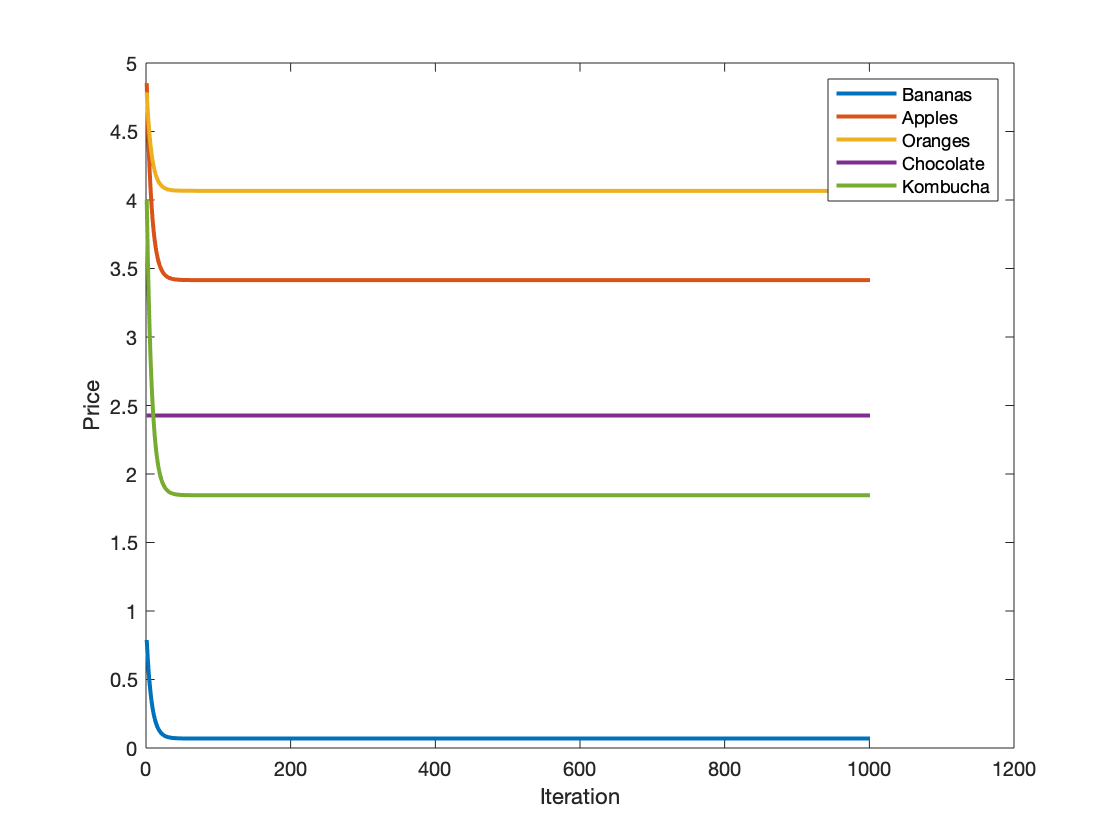


figure()
plot(weights_1ex(1,:),'LineWidth',2)
hold on
plot(weights_1ex(2,:),'LineWidth',2)
hold on
plot(weights_1ex(3,:),'LineWidth',2)
hold on
plot(weights_1ex(4,:),'LineWidth',2)
hold on
plot(weights_1ex(5,:),'LineWidth',2)
xlabel('Iteration')
ylabel('Price')
legend('Bananas','Apples','Oranges','Chocolate','Kombucha')

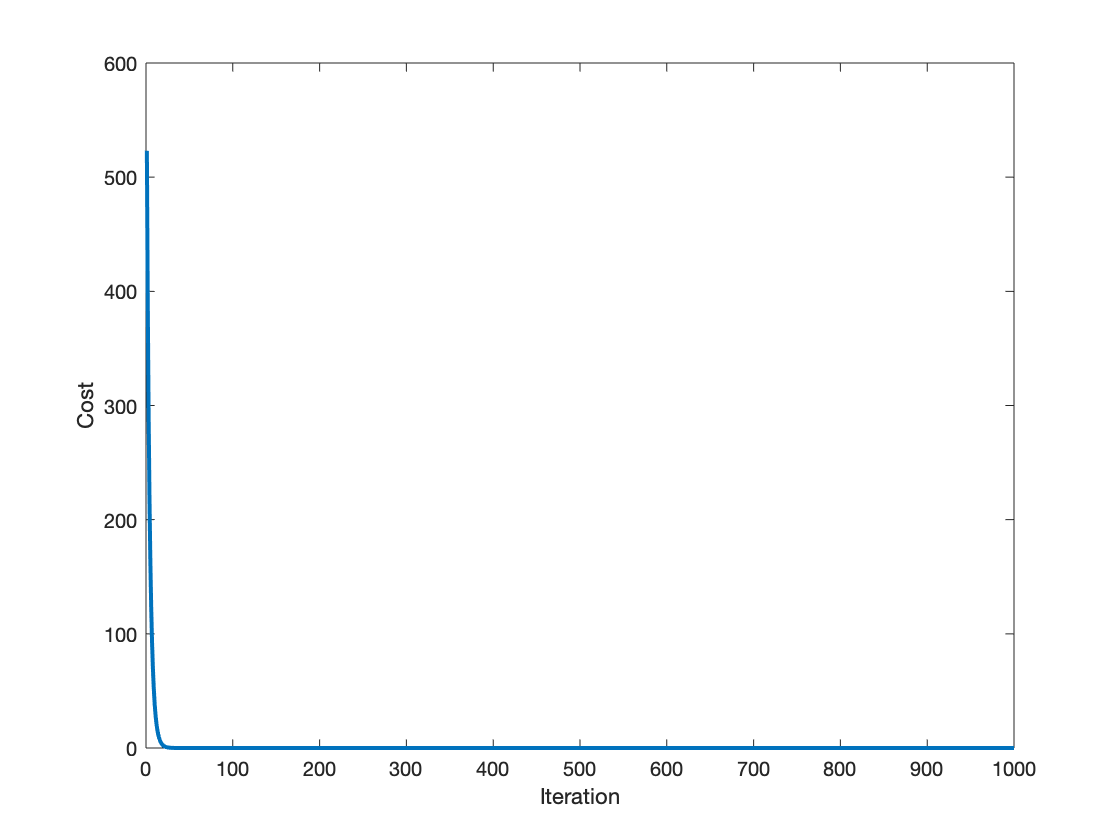

figure()
plot(cost_1ex,'LineWidth',2)
xlabel('Iteration')
ylabel('Cost')

## It gets to low cost, but its estimation of the prices are not generalizable

y_est_1ex_2 = dot(shopping_lists(2,:), weights_1ex(:,end));
y_diff = y_est_1ex_2 - total_prices(2)

y_diff = -4.6357

## How many examples is enough?

n_epochs_nex = 10000;
n_ex = 7;
cost_nex = zeros(1,n_epochs_nex * n_ex);
y_est_nex = zeros(1,n_epochs_nex * n_ex);
weights_ex = zeros(5,n_epochs_nex * n_ex + 1);
weights_ex(:,1) = rand(5,1)*5;
for epoch = 1:n_epochs_nex
    for shopping_run = 1:n_ex
        y_est_nex((epoch -1)*n_ex + shopping_run) = dot(shopping_lists(shopping_run,:), weights_ex(:,(epoch -1)*n_ex + shopping_run));
        cost_nex((epoch -1)*n_ex + shopping_run) = 0.5*(total_prices(shopping_run,:)-y_est_nex((epoch -1)*n_ex + shopping_run))^2;
        dc_dw = 2*0.5*-shopping_lists(shopping_run,:)*(total_prices(shopping_run,:)-y_est_nex((epoch -1)*n_ex + shopping_run));
        weights_ex(:, (epoch -1)*n_ex + shopping_run +1) = weights_ex(:, (epoch -1)*n_ex + shopping_run) - learning_rate * transpose(dc_dw);
    end
end
weights_ex(:,end)

ans =     0.4951
    2.8549
    1.6294
    2.2525
    2.8892


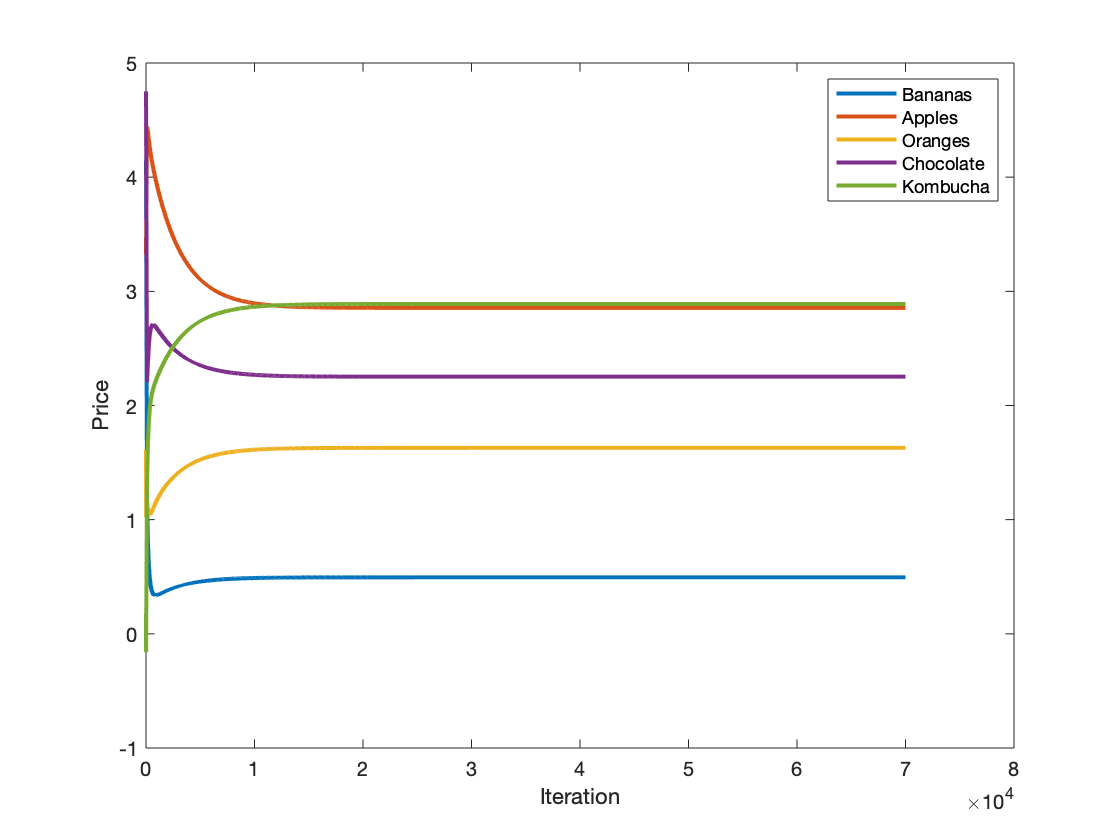


figure()
plot(weights_ex(1,:),'LineWidth',2)
hold on
plot(weights_ex(2,:),'LineWidth',2)
hold on
plot(weights_ex(3,:),'LineWidth',2)
hold on
plot(weights_ex(4,:),'LineWidth',2)
hold on
plot(weights_ex(5,:),'LineWidth',2)
xlabel('Iteration')
ylabel('Price')
legend('Bananas','Apples','Oranges','Chocolate','Kombucha')

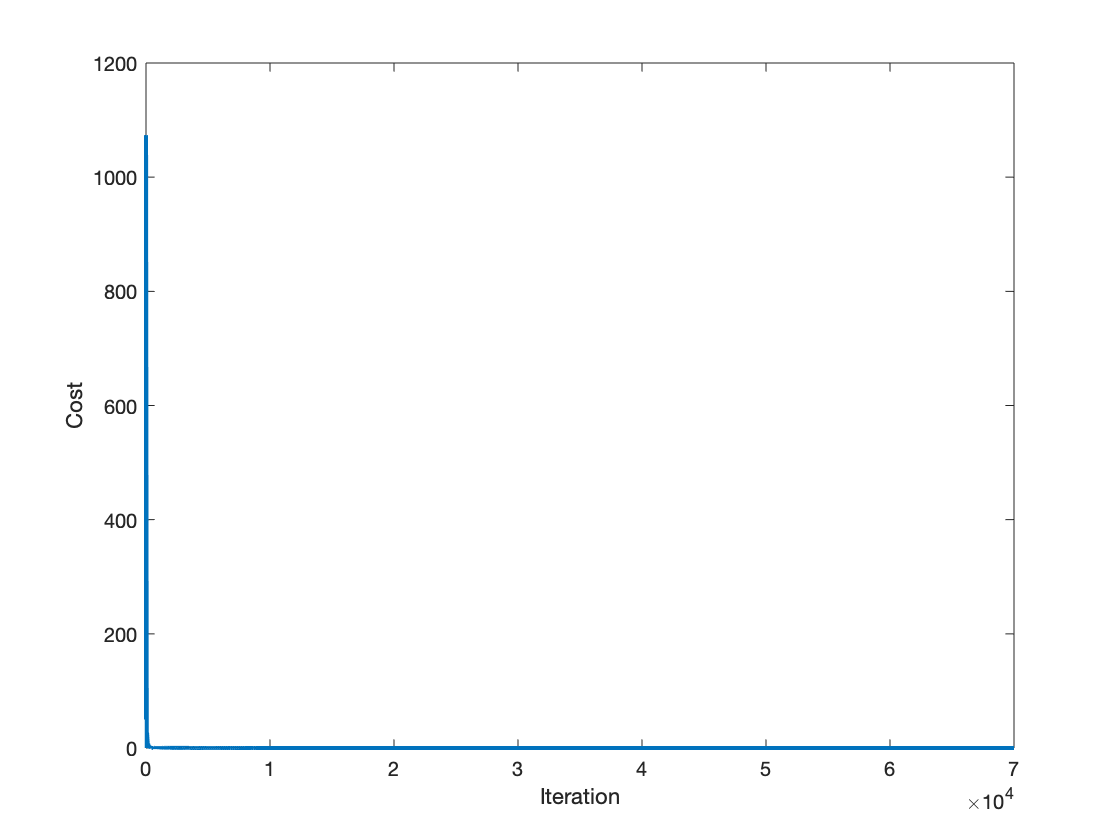


figure()
plot(cost_nex,'LineWidth',2)
xlabel('Iteration')
ylabel('Cost')

y_est_nex_100 = dot(shopping_lists(100,:), weights_ex(:,end));
y_diff_nex = y_est_nex_100 - total_prices(100)

y_diff_nex = 1.7313e-10